% Jep Brinkmann Thesis HMM example
clc; close all;
k = 4;
d = 30;
n = 5;

hmm_options.method = "random";
hmm_options.epsilon = 1/10;

cpd_options.maxIter = 2500;
cpd_options.tol = 1e-14;
cpd_options.epsilon = 1/10;

T_seq = 1e5;

alpha_range = [0.001, 0.0025, 0.005, 0.0075, 0.01, 0.025, 0.05, 0.075 0.1, 0.25, 0.5, 1.0, 5.0];
rho_range = linspace(0, 1, 21);

Nruns = 10;
Cost = zeros(Nruns, length(alpha_range), length(rho_range));

T_hats = cell(n,1);
O_hats = cell(n,1);

P3 = cell(n,1);



for ii = (1:Nruns)
    for i = progress(1:length(alpha_range))
        for j = 1:length(rho_range)
            [T, O, pi, k, d] = generateHMM(k, d, n, hmm_options);
        
            [seq, ~] = generate_multivariate_hmm_sequence(T, O, pi, T_seq);
            for kk = 1:n
                P3{kk} = ProbabilityTensorGenerate(seq(kk, :), 3, d);
            end

            % Coupled CPD
            [T_hat, O_hats, ~, ~] = multivariate_coupled_cpd_2(P3, k, d, n, alpha_range(i), rho_range(j), cpd_options);
            pi_hat = findStationaryDistribution(T_hat')';
            [T_hat, O_hats, ~] = remove_hmm_permutation_transition(T, T_hat, O_hats, pi_hat);
        
            Cost(ii, i, j) = HMMError(T, O, T_hat, O_hats, false);  
        end
    end
end

Processing:  000%  |                                        | 0/13it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                        | 0/13it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                        | 0/13it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                        | 0/13it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                        | 0/13it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                        | 0/13it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                        | 0/13it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                        | 0/13it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                        | 0/13it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                        | 0/13it [00:00:00<Inf:NaN:NaN,



save("PerformanceTests/alpha_rho_performance_cost2.mat", "Cost", "alpha_range", "rho_range")

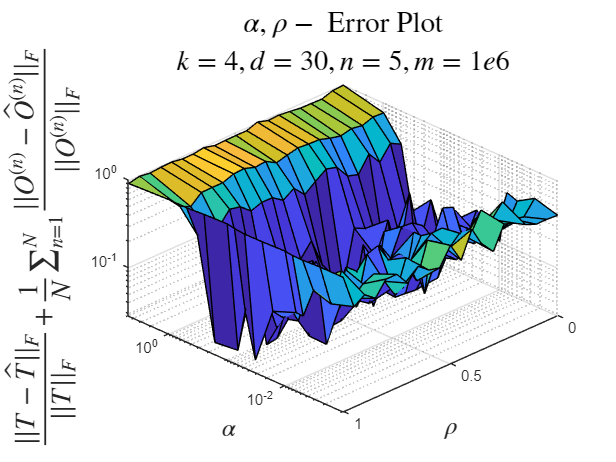

load("PerformanceTests/alpha_rho_performance_cost2")


[cmin, I] = min(squeeze(mean(Cost, 1)), [], "all");
[alphaIndex, rhoIndex] = ind2sub(size(squeeze(sum(Cost, 1))),I);
alpha_best = alpha_range(alphaIndex);
rho_best = rho_range(rhoIndex);


figure()
surf((alpha_range), (rho_range)', squeeze(mean(Cost, 1))');
set(gca,'XScale','log', 'ZScale', 'log');
title("$\alpha, \rho -$ Error Plot", "Interpreter","latex", 'FontWeight','bold', 'FontSize',20)
subtitle("$k=4, d=30, n=5, m=1e6$", "Interpreter","latex", 'FontSize',19)
ylabel("$\rho$", "Interpreter","latex",'FontSize',17,'FontWeight','bold')
xlabel("$\alpha$", "Interpreter","latex",'FontSize',17,'FontWeight','bold')
zlabel("$\frac{||T - \hat{T}||_F}{||T||_F} + \frac{1}{N} \sum_{n=1}^N \frac{||O^{(n)} - \hat{O}^{(n)}||_F}{||O^{(n)}||_F}$", ...
    "Interpreter","latex",'FontSize',19,'FontWeight','bold')
view([-135 , 45])

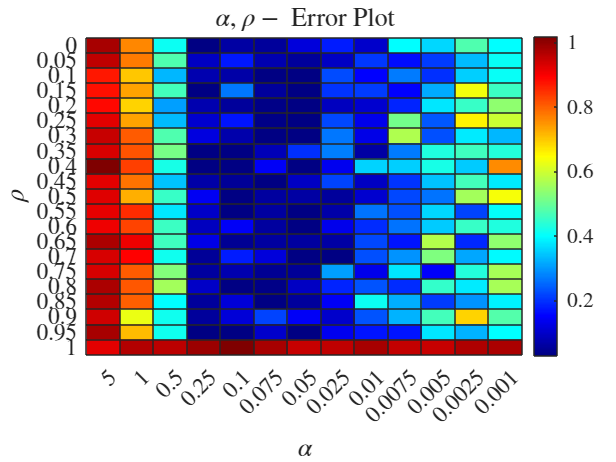


% hgsave(1, ['C:\Users\jepbr\OneDrive\Bureaublad\Systems and Control\Thesis\Figures\AlphaRhoErrorHeatmap.png'], '-v7.3');



figure()
h = heatmap(flip(alpha_range), (rho_range), flip(squeeze(mean(Cost, 1))', 2), Colormap=jet());
title("$\alpha, \rho -$ Error Plot")
% subtitle("$k=4, d=30, n=5, m=1e6$")
h.CellLabelColor = "none";
h.YLabel = "$\rho$";
h.XLabel = "$\alpha$";
h.FontSize = 16;
h.Interpreter = 'latex';